# Fetal EKG extraction from abdominal EKG

Load data abdominal ekg and fetal ekg for reference

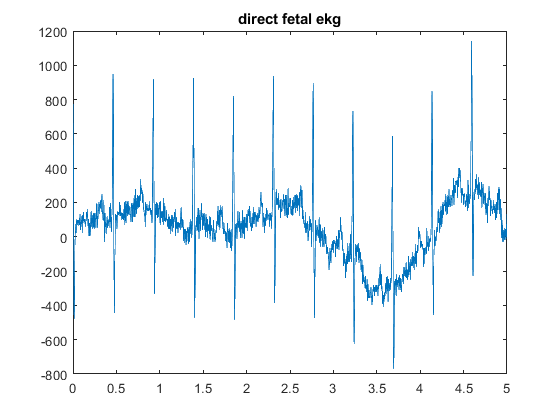

clear
cd 'C:\Users\Anggara\Documents\Skripshit\program\data1'
load('fekgShort.mat')
plot(x,fekg);
title('direct fetal ekg')

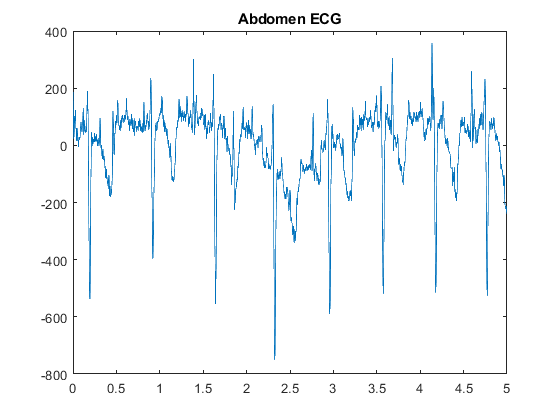

figure
abd=abd1;
plot(x,abd);
title('Abdomen ECG')

## Wavelet Decomposision

[c,l]=wavedec(abd,10,'sym4');

## BW Removal

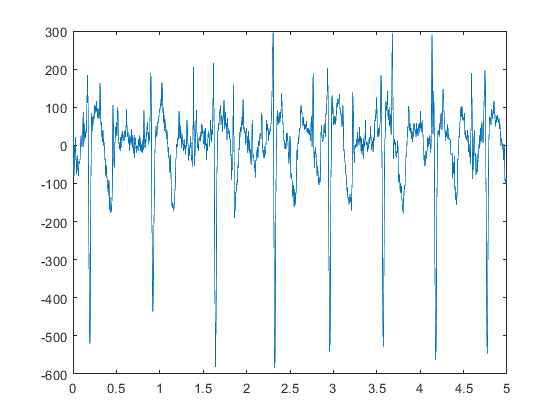

a=wrcoef('a',c,l,'sym4',8);
abd_noBW=abd-a;
% figure
% plot(x,a)
figure
plot(x,abd_noBW)

## Denoising

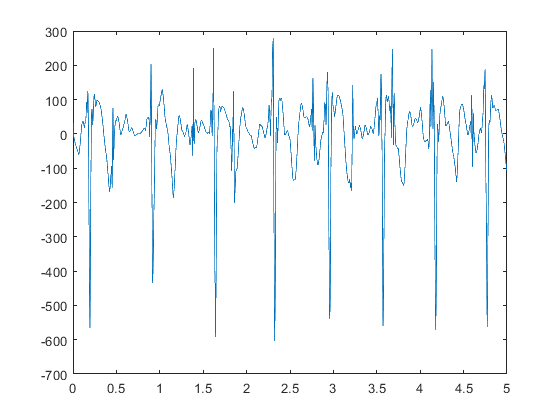

abd_den = wdenoise(abd_noBW,5, ...
    'Wavelet', 'sym4', ...
    'DenoisingMethod', 'UniversalThreshold', ...
    'ThresholdRule', 'Hard', ...
    'NoiseEstimate', 'LevelDependent');
figure
plot(x,abd_den)

## Peak and valley detection

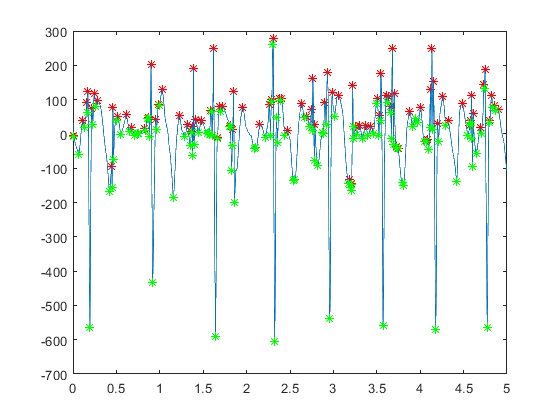

abd_max=islocalmax(abd_den);
abd_min=islocalmin(abd_den);
figure
plot(x,abd_den,'b',...
    x(abd_max),abd_den(abd_max),'r*',...
    x,abd_den,x(abd_min),abd_den(abd_min),'g*')

## Amplitude of peak followed by next valley

    if the first signal is valley, delete the first valley

i=find(abd_max);
j=find(abd_min);
if i(1)>j(1)
    abd_min(j(1))=0;
    for n=1:length(j)-1
        j(n)=j(n+1);
    end
    j(length(j))=[];
end
if length(i)>length(j)
    abd_max(max(i))=0;
    i(length(i))=[];
end
abd_peak=abd_den(abd_max)';
abd_valley=abd_den(abd_min)';
abd_amp=abd_peak-abd_valley;
ns=j-i;
% ksdensity(abd_amp)

## Clustering

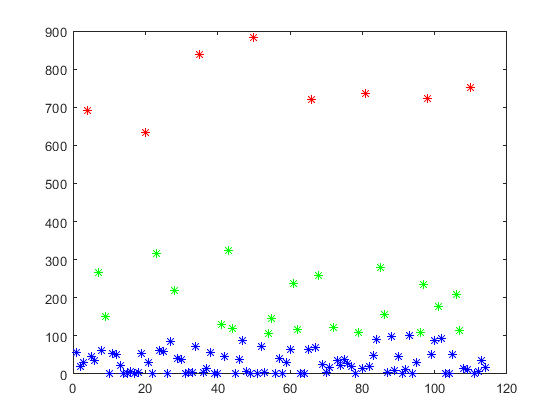

[abd_clus,Cent]=kmeans(abd_amp,3);
xclus=1:length(abd_amp);
figure
plot(xclus(abd_clus==1),abd_amp(abd_clus==1),'b*',...
    xclus(abd_clus==2),abd_amp(abd_clus==2),'r*',...
    xclus(abd_clus==3),abd_amp(abd_clus==3),'g*')

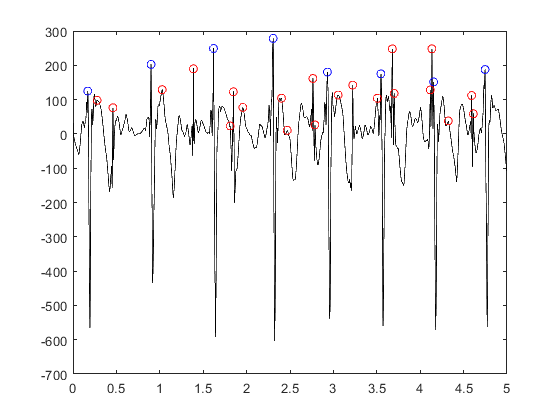

[~,I]=sort(Cent);
abd_clus1=abd_amp(abd_clus==I(3));
abd_clus2=abd_amp(abd_clus==I(2));
abd_clus3=abd_amp(abd_clus==I(1));
abd_peak1=zeros(length(abd_clus1),1);
abd_peak2=zeros(length(abd_clus2),1);
abd_peak3=zeros(length(abd_clus3),1);
for m=1:length(abd_clus1)
    abd_peak1(m)=find(abd_amp==abd_clus1(m));
    abd_peak1(m)=abd_peak(abd_peak1(m));
    abd_peak1(m)=find(abd_den==abd_peak1(m));
end
for m=1:length(abd_clus2)
    abd_peak2(m)=find(abd_amp==abd_clus2(m));
    abd_peak2(m)=abd_peak(abd_peak2(m));
    abd_peak2(m)=find(abd_den==abd_peak2(m));
end
for m=1:length(abd_clus3)
    abd_peak3(m)=find(abd_amp==abd_clus3(m));
    abd_peak3(m)=abd_peak(abd_peak3(m));
    abd_peak3(m)=find(abd_den==abd_peak3(m));
end
figure
plot(x,abd_den,'k',x(abd_peak1),abd_den(abd_peak1),'bo')
hold on
plot(x(abd_peak2),abd_den(abd_peak2),'ro')
hold off

## Clustering Mekg first then Fekg

(when the fekg QRS peak hardly noticeable)

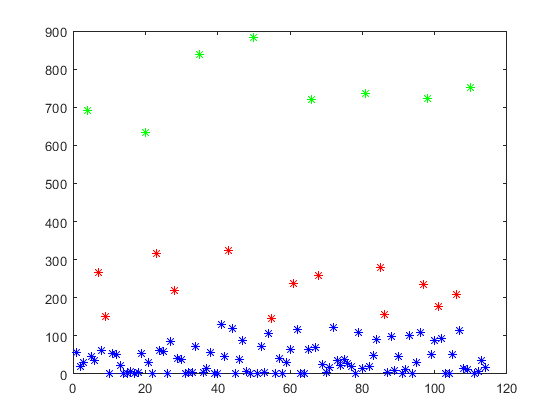

[abd_clus,Cent]=kmeans(abd_amp,3);
xclus=1:length(abd_amp);
figure
plot(xclus(abd_clus==1),abd_amp(abd_clus==1),'b*',...
    xclus(abd_clus==2),abd_amp(abd_clus==2),'r*',...
    xclus(abd_clus==3),abd_amp(abd_clus==3),'g*')

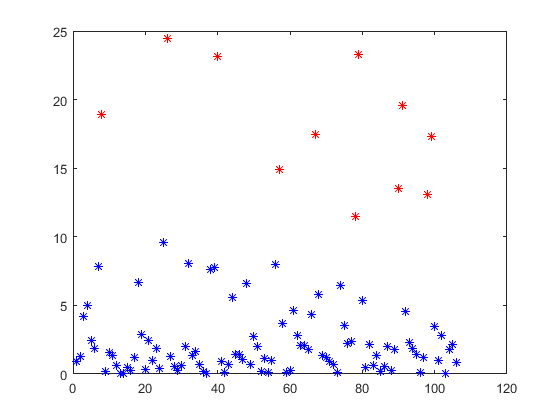

[~,I]=sort(Cent);
abd_clus1=abd_amp(abd_clus==I(3));
abd_cl2=find(abd_clus==I(2)|abd_clus==I(1));
abd_cl23=abd_amp(abd_cl2)./(ns(abd_cl2)');
[abd_clus23,Cen2]=kmeans(abd_cl23,2);
xclus2=1:length(abd_amp);
% abd_cl23n=abd_cl23.*(ns(abd_cl2)');
figure
plot(xclus2(abd_clus23==1),abd_cl23(abd_clus23==1),'b*',...
    xclus2(abd_clus23==2),abd_cl23(abd_clus23==2),'r*')

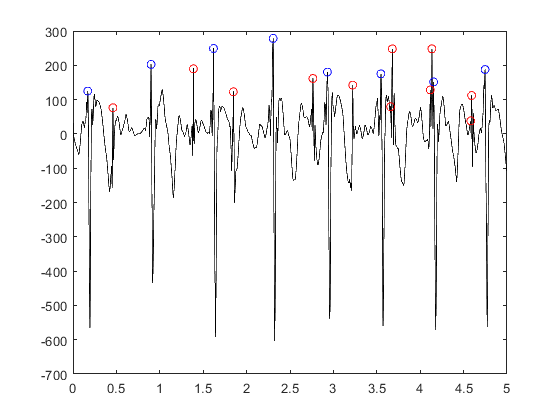

ns2=ns(abd_cl2)';
abd_cl23n=abd_cl23.*ns2;
[~,I2]=sort(Cen2);
abd_clus2=abd_cl23n(abd_clus23==I2(2));
abd_clus3=abd_cl23n(abd_clus23==I2(1));
abd_peak1=zeros(length(abd_clus1),1);
abd_peak2=zeros(length(abd_clus2),1);
abd_peak3=zeros(length(abd_clus3),1);
abd_amp=round(abd_amp,8);
for m=1:length(abd_clus1)
    abd_peak1(m)=find(abd_amp==round(abd_clus1(m),8));
    abd_peak1(m)=abd_peak(abd_peak1(m));
    abd_peak1(m)=find(abd_den==abd_peak1(m));
end
for m=1:length(abd_clus2)
    abd_peak2(m)=find(abd_amp==round(abd_clus2(m),8));
    abd_peak2(m)=abd_peak(abd_peak2(m));
    abd_peak2(m)=find(abd_den==abd_peak2(m));
end
for m=1:length(abd_clus3)
    abd_peak3(m)=find(abd_amp==round(abd_clus3(m),8));
    abd_peak3(m)=abd_peak(abd_peak3(m));
    abd_peak3(m)=find(abd_den==abd_peak3(m));
end
figure
plot(x,abd_den,'k',x(abd_peak1),abd_den(abd_peak1),'bo')
hold on
plot(x(abd_peak2),abd_den(abd_peak2),'ro')
hold off

## Clustering Case 2

(when amplitude of fekg and mekg is too similar)

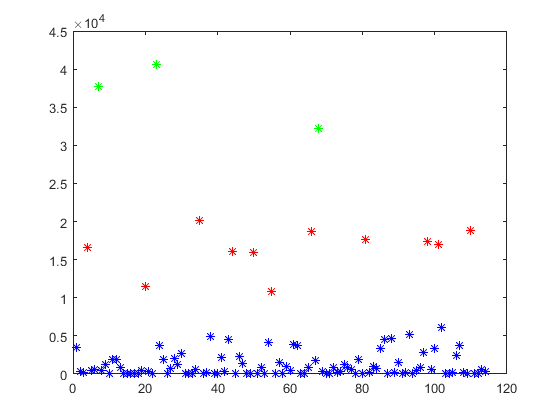

ns=j-i;
abd_ampns=abd_amp.*(ns');
% figure
% histogram(abd_ampns,100)
% ksdensity(abd_ampns)
[abd_clusns,Centns]=kmeans(abd_ampns,3);
xclusns=1:length(abd_ampns);
figure
plot(xclusns(abd_clusns==1),abd_ampns(abd_clusns==1),'b*',...
    xclusns(abd_clusns==2),abd_ampns(abd_clusns==2),'r*',...
    xclusns(abd_clusns==3),abd_ampns(abd_clusns==3),'g*')

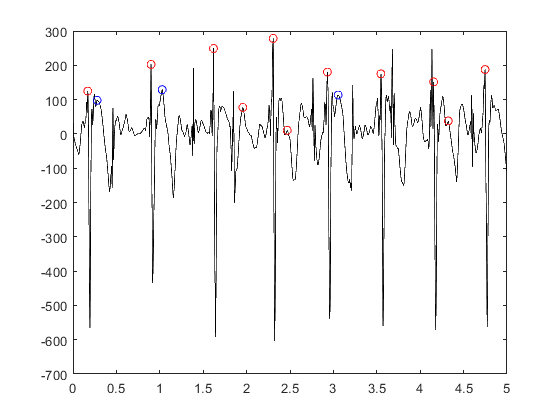

[~,Ins]=sort(Centns);
abd_clusns1=abd_ampns(abd_clusns==Ins(3));
abd_clusns2=abd_ampns(abd_clusns==Ins(2));
abd_clusns3=abd_ampns(abd_clusns==Ins(1));
abd_peakns1=zeros(length(abd_clusns1),1);
abd_peakns2=zeros(length(abd_clusns2),1);
abd_peakns3=zeros(length(abd_clusns3),1);
for m=1:length(abd_clusns1)
    abd_peakns1(m)=find(abd_ampns==abd_clusns1(m));
    abd_peakns1(m)=abd_peak(abd_peakns1(m));
    abd_peakns1(m)=find(abd_den==abd_peakns1(m));
end
for m=1:length(abd_clusns2)
    abd_peakns2(m)=find(abd_ampns==abd_clusns2(m));
    abd_peakns2(m)=abd_peak(abd_peakns2(m));
    abd_peakns2(m)=find(abd_den==abd_peakns2(m));
end
for m=1:length(abd_clusns3)
    abd_peakns3(m)=find(abd_ampns==abd_clusns3(m));
    abd_peakns3(m)=abd_peak(abd_peakns3(m));
    abd_peakns3(m)=find(abd_den==abd_peakns3(m));
end
figure
plot(x,abd_den,'k',x(abd_peakns1),abd_den(abd_peakns1),'bo')
hold on
plot(x(abd_peakns2),abd_den(abd_peakns2),'ro')
hold off

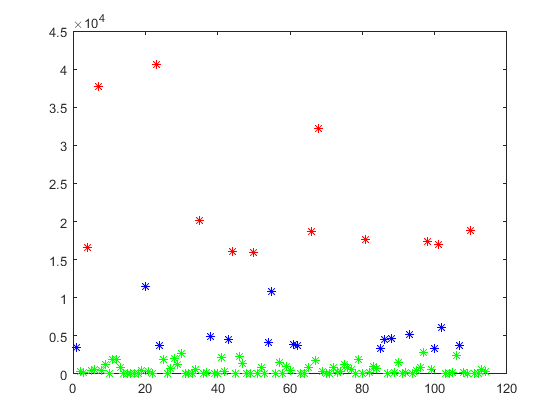

[abd_clusns,Centns]=kmeans(abd_ampns,3);
xclusns=1:length(abd_ampns);
figure
plot(xclusns(abd_clusns==1),abd_ampns(abd_clusns==1),'b*',...
    xclusns(abd_clusns==2),abd_ampns(abd_clusns==2),'r*',...
    xclusns(abd_clusns==3),abd_ampns(abd_clusns==3),'g*')

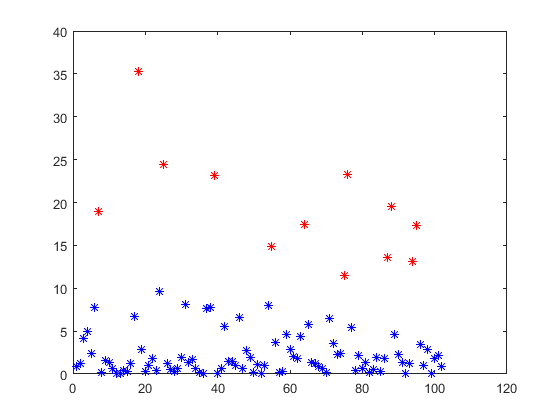

[~,Ins]=sort(Centns);
abd_clusns1=abd_ampns(abd_clusns==Ins(3));
abd_clns2=find(abd_clusns==Ins(2)|abd_clusns==Ins(1));
abd_clns23=abd_ampns(abd_clns2)./((ns(abd_clns2)').^2);
[abd_clusns23,Cen2]=kmeans(abd_clns23,2);
xclusns2=1:length(abd_ampns);
% abd_cl23n=abd_cl23.*(ns(abd_cl2)');
figure
plot(xclusns2(abd_clusns23==1),abd_clns23(abd_clusns23==1),'b*',...
    xclusns2(abd_clusns23==2),abd_clns23(abd_clusns23==2),'r*')

ns2=ns(abd_clns2)';
abd_clns23n=abd_clns23.*ns2.^2;
[~,Ins2]=sort(Cen2);
abd_clusns2=abd_clns23n(abd_clusns23==Ins2(2));
abd_clusns3=abd_clns23n(abd_clusns23==Ins2(1));
abd_peakns1=zeros(length(abd_clusns1),1);
abd_peakns2=zeros(length(abd_clusns2),1);
abd_peakns3=zeros(length(abd_clusns3),1);
abd_ampns=round(abd_ampns,8);
for m=1:length(abd_clusns1)
    abd_peakns1(m)=find(abd_ampns==round(abd_clusns1(m),8));
    abd_peakns1(m)=abd_peak(abd_peakns1(m));
    abd_peakns1(m)=find(abd_den==abd_peakns1(m));
end
for m=1:length(abd_clusns2)
    abd_peakns2(m)=find(abd_ampns==round(abd_clusns2(m),8));
    abd_peakns2(m)=abd_peak(abd_peakns2(m));
    abd_peakns2(m)=find(abd_den==abd_peakns2(m));
end
for m=1:length(abd_clusns3)
    abd_peakns3(m)=find(abd_ampns==round(abd_clusns3(m),8));
    abd_peakns3(m)=abd_peak(abd_peakns3(m));
    abd_peakns3(m)=find(abd_den==abd_peakns3(m));
end
figure
plot(x,abd_den,'k',x(abd_peakns1),abd_den(abd_peakns1),'bo')
hold on
plot(x(abd_peakns2),abd_den(abd_peakns2),'ro')
hold off